#  KNM2 - qU=E0-300V Rate Monitor FPD

##  Stacked-pixel Evolution 

###   T. Lasserre - Last Modified: 17/10/2019

### Relevant Run Lists

### KNM2_Prompt

### KNM2_beforeFix

### KNM2_afterFix

%% Read Data
DataType = 'Real';
RunList = 'KNM2_afterFix';
FSDFlag = 'BlindingKNM2';
ELossFlag = 'KatrinT2';
AnaFlag = 'StackPixel'; % uniform FPD
RunAnaArg = {'NonPoissonScaleFactor',1.1,'RunList',RunList,'DataType',DataType,...
            'FSDFlag',FSDFlag,'ELossFlag',ELossFlag,'AnaFlag',AnaFlag};
A = MultiRunAnalysis(RunAnaArg{:});

-------------------Start MultiRunAnalysis Constructor----------------- 
---------------------Start RunAnalysis Constructor------------------- 
---------------------End RunAnalysis Constructor------------------- 
no new runs to convert 
ApplyStackingCuts: Exit Cut Routine after 1 Iterations 
Showing Stacked Data (data for Ring selected later) 
../../tritium-data/mat/Knm2/KNM2_afterFix
loading response function from file: ../../inputs/ResponseFunction/samakRF_Uniform_4.2489e+17cm2_IsX3.637e-22m2_NIS7_Bm4.23T_Bs2.52T_Ba6.311G_Temin18484.087_Temax18709.095_Bin100_KatrinT2.mat


## Slow Control Data

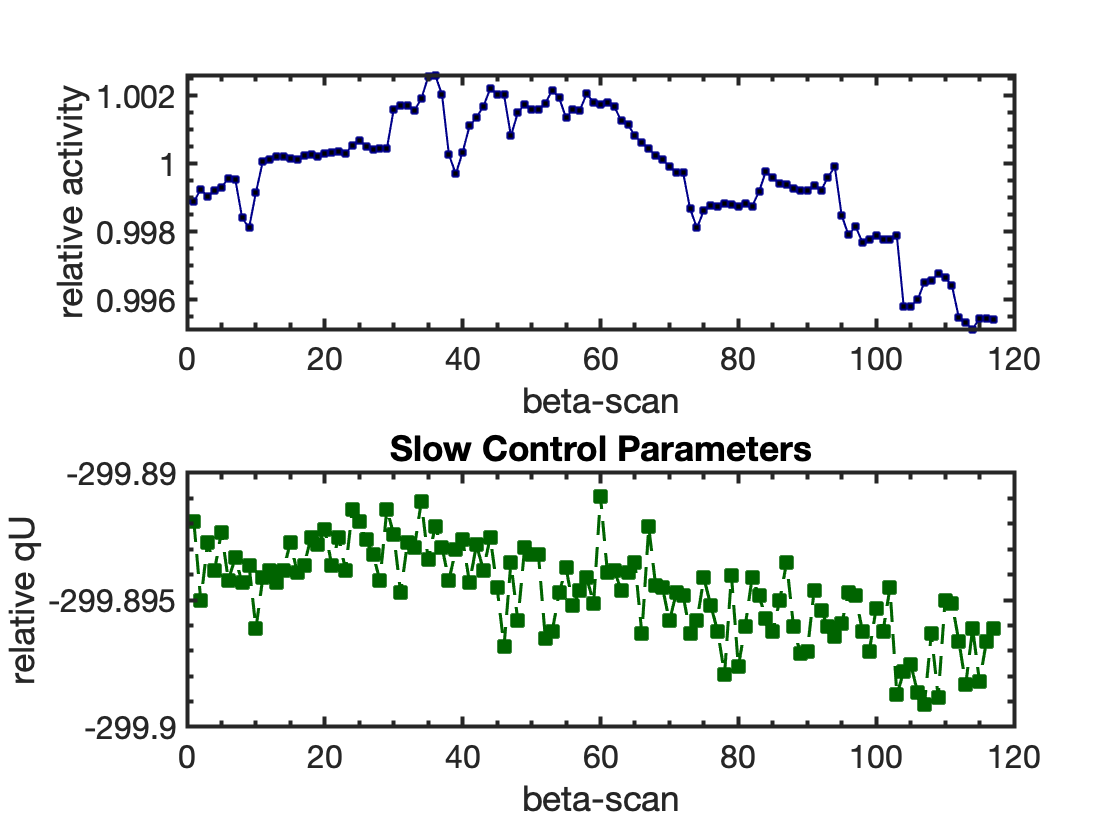

p1 =(A.SingleRunData.WGTS_MolFrac_TT'+0.5*A.SingleRunData.WGTS_MolFrac_HT'+0.5*A.SingleRunData.WGTS_MolFrac_DT')./median((A.SingleRunData.WGTS_MolFrac_TT'+0.5*A.SingleRunData.WGTS_MolFrac_HT'+0.5*A.SingleRunData.WGTS_MolFrac_DT')).*A.SingleRunData.WGTS_CD_MolPerCm2'./median(A.SingleRunData.WGTS_CD_MolPerCm2');
p2 = mean(A.SingleRunData.qU_RM,1); p2=p2-18574; %p2=p2-mean(p2);      
subplot(2,1,1)
plot(p1,'s-','Color',rgb('DarkBlue'),'LineWidth',1,'MarkerSize',4,'markerfacecolor','Black');
ylabel('relative activity');
xlabel('beta-scan');
PrettyFigureFormat
subplot(2,1,2)
plot(p2,'s--','Color',rgb('DarkGreen'),'LineWidth',1,'MarkerSize',8,'markerfacecolor',rgb('DarkGreen'));
ylabel('relative qU');
xlabel('beta-scan');
PrettyFigureFormat
title(sprintf('Slow Control Parameters'));

## Stacked Pixel Data

couns at -300 V - here we sum the counts over all golden piwels

count  = sum(A.SingleRunData.TBDIS_RM,1);

sub-scan time - Average of the sub-scan times

sstime = mean(A.SingleRunData.qUfrac_RM,1).*A.SingleRunData.TimeSec;

Rate in cps

rate   = count./sstime;

Correction factor based on qU and Tritium activity

%cf     = A.RMRateErosCorrectionqUActivity;

Correction factor based on qU and rhod, tt, ht, d

%cf     = A.R200RateErosCorrection;

Correction based on the activity only

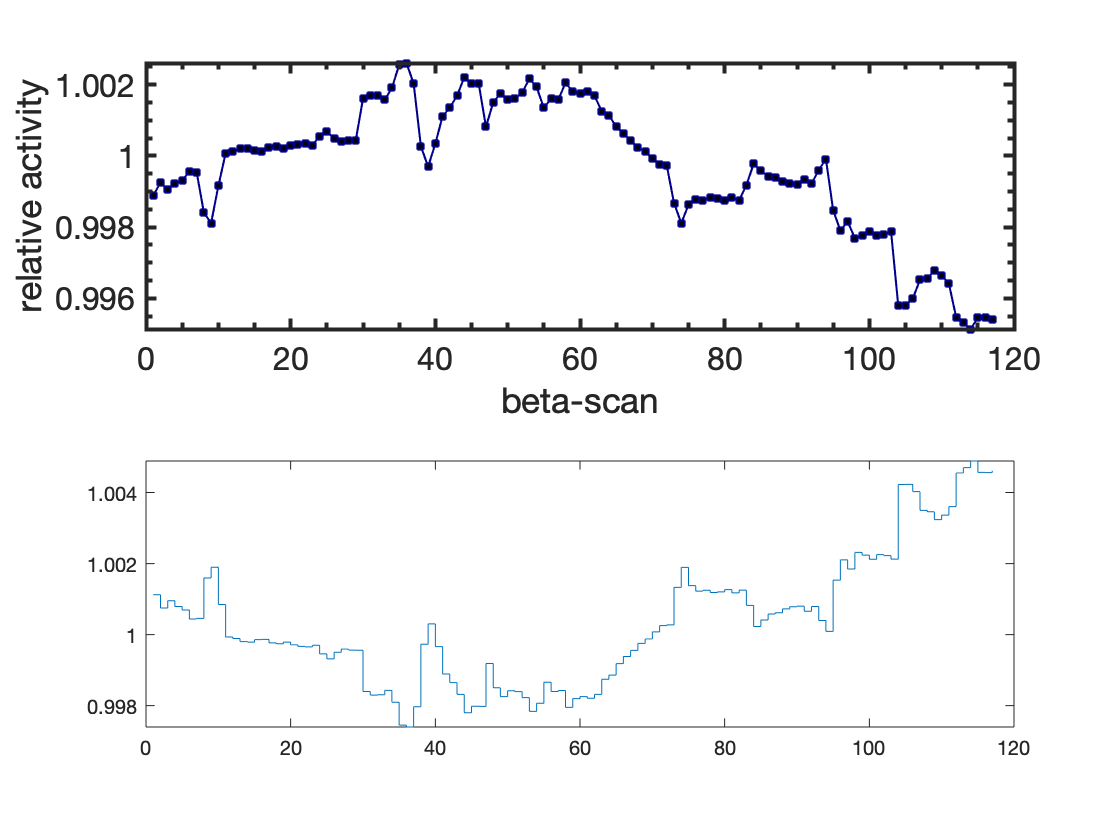

cf = 1./p1';
stairs(cf);

Counts, renormalized to the average time

count_norm     = rate .* mean(sstime);

Counts, renormalized to the average time, with rate correction effective

corrcount_norm = count_norm .* cf;

## Stacked Pixel Histogram - Raw & Corrected Rates

Top: raw rate

Bottom: Corrected rates: qU & Tritium Activity

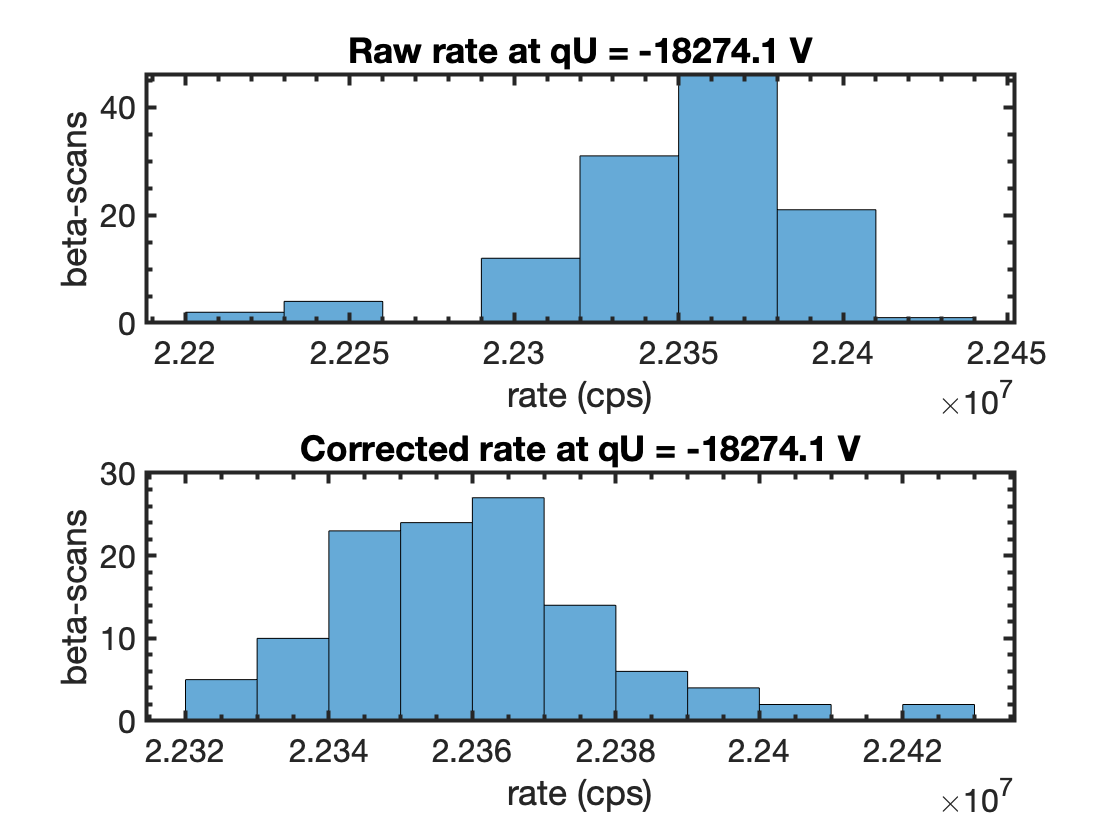

subplot(2,1,1)
histogram(count_norm);
PrettyFigureFormat
xlabel('rate (cps)');
ylabel('beta-scans');
title(sprintf('Raw rate at qU = -%.1f V',mean(mean(A.SingleRunData.qU_RM))));
subplot(2,1,2)
histogram(corrcount_norm);
PrettyFigureFormat
xlabel('rate (cps)');
ylabel('beta-scans');
title(sprintf('Corrected rate at qU = -%.1f V',mean(mean(A.SingleRunData.qU_RM))));

## Stacked Pixel Evolution - Raw Rate - Corrected Rate

Top: correction factor in rate (cps) - A one per mille effect

Bottom : rate as a function of run - green=raw - red=corrected

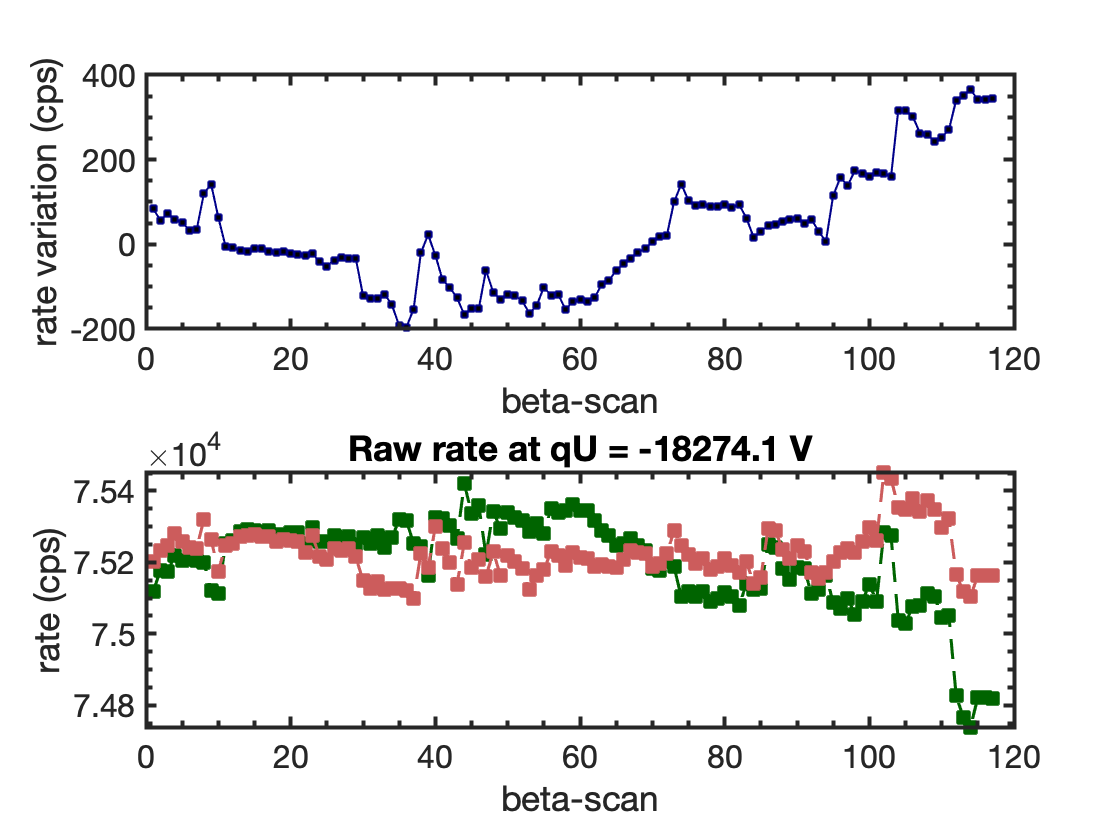

subplot(2,1,1)
plot((cf-1).*rate,'s-','Color',rgb('DarkBlue'),'LineWidth',1,'MarkerSize',4,'markerfacecolor','Black');
ylabel('rate variation (cps)');
xlabel('beta-scan');
PrettyFigureFormat
subplot(2,1,2)
plot(rate,'s--','Color',rgb('DarkGreen'),'LineWidth',1,'MarkerSize',8,'markerfacecolor',rgb('DarkGreen'));
hold on
plot(rate.*cf,'s--','Color',rgb('IndianRed'),'LineWidth',1,'MarkerSize',8,'markerfacecolor',rgb('IndianRed'));
hold off
ylabel('rate (cps)');
xlabel('beta-scan');
PrettyFigureFormat
title(sprintf('Raw rate at qU = -%.1f V',mean(mean(A.SingleRunData.qU_RM))));

## Stacked Pixel: Non-Poissonian Component?

Take count histogram

Fit Gaussian - m - sigma

Fit Poisson - lambda - sqrt(lambda)

Compare fit parameters, especially their width

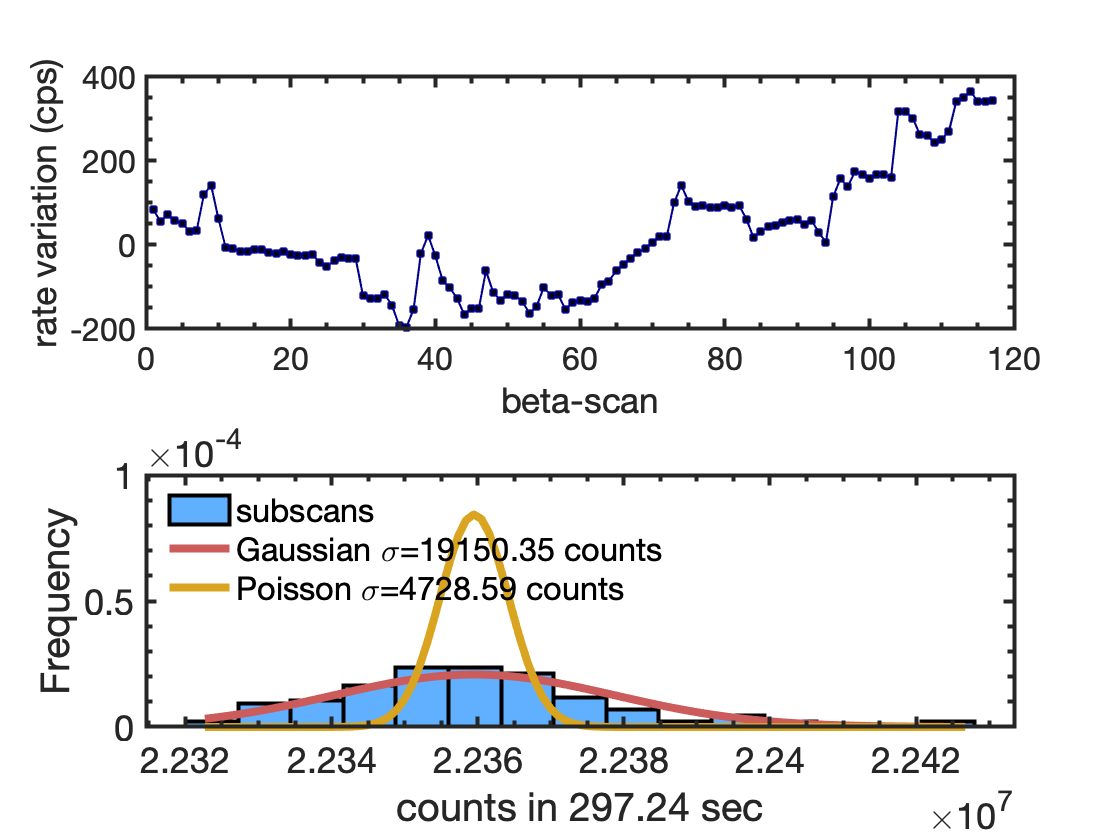

pdG = fitdist(corrcount_norm','Normal');
pdN = fitdist(corrcount_norm','poisson');
savefile    = sprintf('plots/test.png');
h = histogram(corrcount_norm,15,'Normalization','pdf',...
    'FaceColor',rgb('DodgerBlue'),'LineWidth',2,'FaceAlpha',0.7);
xlabel(sprintf('counts in %.2f sec',mean(sstime)));
ylabel('Frequency');
PrettyFigureFormat
% Gaussian PDF
pdfG = @(b) 1/sqrt(2*pi*pdG.sigma.^2) .* exp(-(b-pdG.mu).^2/(2*pdG.sigma.^2));
% Poisson PDF
pdfP = @(b) 1/sqrt(2*pi*pdN.lambda) .* exp(-(b-pdN.lambda).^2/(2*pdN.lambda));
hold on
b = linspace(min(corrcount_norm),max(corrcount_norm),100);
g=plot(b,pdfG(b),'Color',rgb('IndianRed'),'LineWidth',4);
p=plot(b,pdfP(b),'Color',rgb('GoldenRod'),'LineWidth',4);
leg=legend([h g p],...
    sprintf('subscans'),...
    sprintf('Gaussian \\sigma=%.2f counts',...
    (pdG.sigma)),sprintf('Poisson \\sigma=%.2f counts',sqrt(pdN.lambda)),...
    'location','northwest');
leg.Color = 'none'; legend boxoff;
hold off
PrettyFigureFormat
set(gca,'FontSize',18);

## 1 sigma uncertainty on sigma(Gauss) 

SigmaErrGauss = sqrt(pdG.ParameterCovariance(2,2));

## 1 sigma uncertainty on sigma(Poisson) 

SigmaErrPoiss = sqrt(sqrt(pdN.ParameterCovariance));

## Uncertainty on the ratio Gauss/Poisson

SigmaGauss = pdG.sigma;
SigmaPoiss = sqrt(pdN.lambda);
NPfactor = SigmaGauss./SigmaPoiss;
NPfactorErr = sqrt((1./SigmaPoiss.*SigmaErrGauss).^2+(SigmaGauss./SigmaPoiss.^2.*SigmaErrPoiss).^2);

## Stacked Pixel: Non-Poissonian Component Calculation in %

fprintf('NP ratio = %.3f +- %.3f ',...
    ((pdG.sigma/sqrt(pdN.lambda))),...
    NPfactorErr);

NP ratio = 4.050 +- 0.267 

## Is the any trend in the correction?

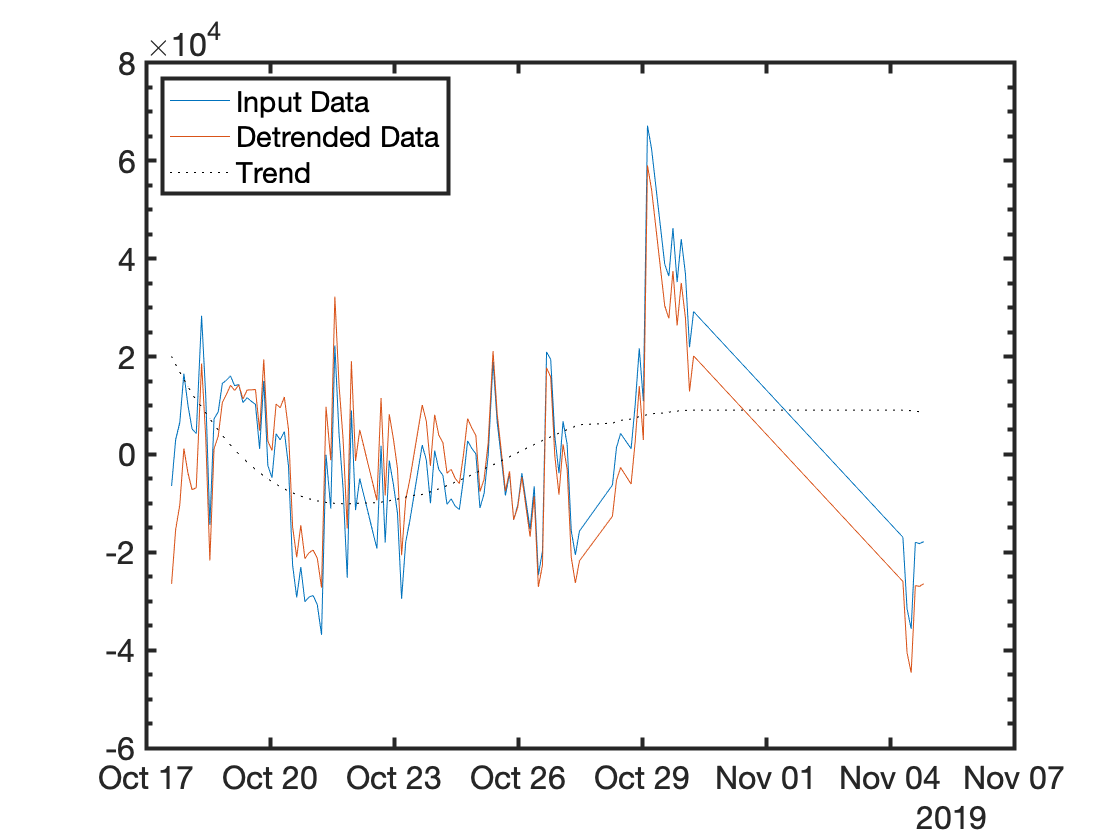

figure
 t = A.SingleRunData.StartTimeStamp;
 x = corrcount_norm-mean(corrcount_norm);
 %x=p2;
 y = detrend(x,3);
 plot(t,x,t,y,t,x-y,':k')
 legend('Input Data','Detrended Data','Trend','Location','northwest') ;
 PrettyFigureFormat

## Compute Mean / Variance Before Fix RW & After Fix RW Voltage

 AbeforeFix = MultiRunAnalysis(RunAnaArg{:},'RunList','KNM2_beforeFix');

-------------------Start MultiRunAnalysis Constructor----------------- 
---------------------Start RunAnalysis Constructor------------------- 
---------------------End RunAnalysis Constructor------------------- 
no new runs to convert 
ApplyStackingCuts: Exit Cut Routine after 2 Iterations 
Showing Stacked Data (data for Ring selected later) 
../../tritium-data/mat/Knm2/KNM2_beforeFix
loading response function from file: ../../inputs/ResponseFunction/samakRF_Uniform_4.2397e+17cm2_IsX3.637e-22m2_NIS7_Bm4.23T_Bs2.52T_Ba6.311G_Temin18484.100_Temax18709.096_Bin100_KatrinT2.mat


 AafterFix  = MultiRunAnalysis(RunAnaArg{:},'RunList','KNM2_afterFix');

-------------------Start MultiRunAnalysis Constructor----------------- 
---------------------Start RunAnalysis Constructor------------------- 
---------------------End RunAnalysis Constructor------------------- 
no new runs to convert 
ApplyStackingCuts: Exit Cut Routine after 1 Iterations 
Showing Stacked Data (data for Ring selected later) 
../../tritium-data/mat/Knm2/KNM2_afterFix
loading response function from file: ../../inputs/ResponseFunction/samakRF_Uniform_4.2489e+17cm2_IsX3.637e-22m2_NIS7_Bm4.23T_Bs2.52T_Ba6.311G_Temin18484.087_Temax18709.095_Bin100_KatrinT2.mat



 
 count  = sum(AbeforeFix.SingleRunData.TBDIS_RM,1);
 sstime = mean(AbeforeFix.SingleRunData.qUfrac_RM,1).*AbeforeFix.SingleRunData.TimeSec;
 rate   = count./sstime;
 %cf     = AbeforeFix.R200RateErosCorrection;
 cf = 1./((AbeforeFix.SingleRunData.WGTS_MolFrac_TT'+0.5*AbeforeFix.SingleRunData.WGTS_MolFrac_HT'+0.5*AbeforeFix.SingleRunData.WGTS_MolFrac_DT')./median((A.SingleRunData.WGTS_MolFrac_TT'+0.5*A.SingleRunData.WGTS_MolFrac_HT'+0.5*A.SingleRunData.WGTS_MolFrac_DT')).*AbeforeFix.SingleRunData.WGTS_CD_MolPerCm2'./median(A.SingleRunData.WGTS_CD_MolPerCm2'));
 count_norm     = rate .* mean(sstime);
 corrcount_norm = count_norm .* cf';
 before = corrcount_norm;
 pdGbefore = fitdist(before','Normal');
 meanBefore = pdGbefore.mu

meanBefore =      2.239028544133520e+07


 meanErrorBefore = sqrt(pdGbefore.ParameterCovariance(1,1))

meanErrorBefore =      1.838177792849887e+03


 
 count  = sum(AafterFix.SingleRunData.TBDIS_RM,1);
 sstime = mean(AafterFix.SingleRunData.qUfrac_RM,1).*AafterFix.SingleRunData.TimeSec;
 rate   = count./sstime;
 %cf     = AafterFix.R200RateErosCorrection;
 cf = 1./((AafterFix.SingleRunData.WGTS_MolFrac_TT'+0.5*AafterFix.SingleRunData.WGTS_MolFrac_HT'+0.5*AafterFix.SingleRunData.WGTS_MolFrac_DT')./median((A.SingleRunData.WGTS_MolFrac_TT'+0.5*A.SingleRunData.WGTS_MolFrac_HT'+0.5*A.SingleRunData.WGTS_MolFrac_DT')).*AafterFix.SingleRunData.WGTS_CD_MolPerCm2'./median(A.SingleRunData.WGTS_CD_MolPerCm2'));
 count_norm     = rate .* mean(sstime);
 corrcount_norm = count_norm .* cf';
 after = corrcount_norm ;
 pdGafter = fitdist(after','Normal');
 meanAfter= pdGafter.mu

meanAfter =      2.235952375581823e+07


 meanErrorAfter = sqrt(pdGafter.ParameterCovariance(1,1))

meanErrorAfter =      1.770450270395771e+03


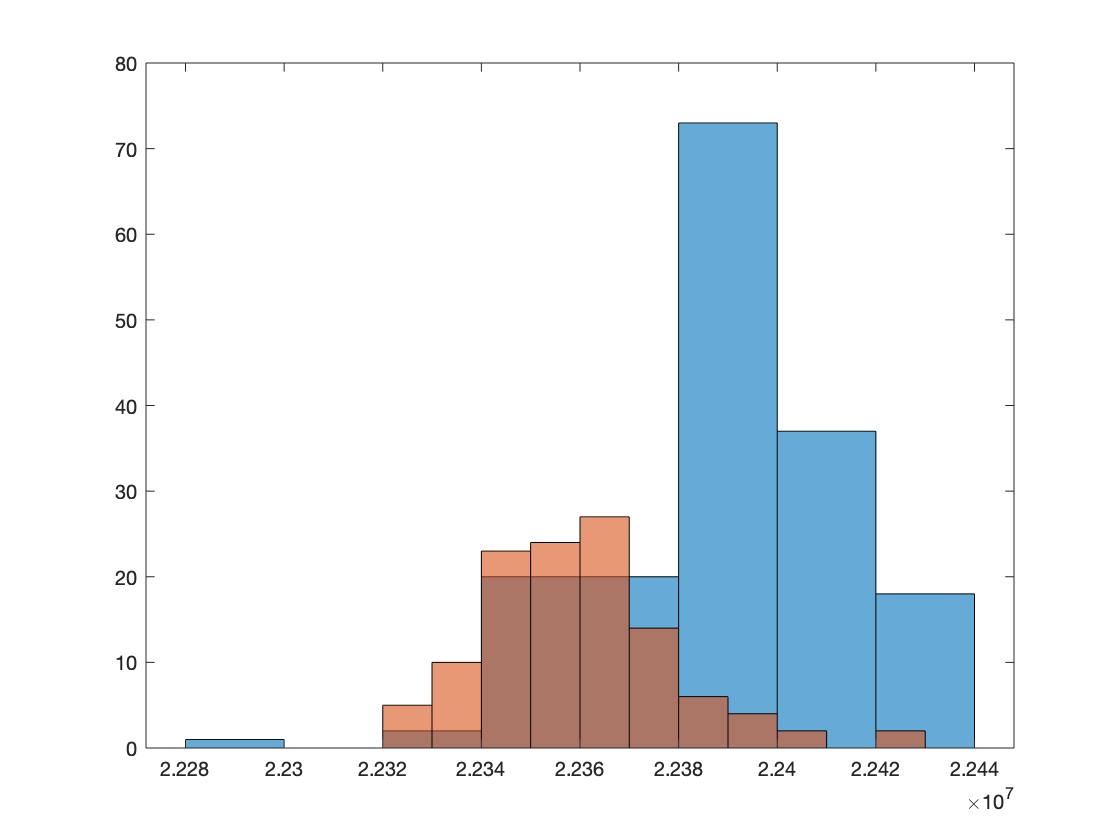

histogram(before)
hold on
histogram(after)
hold off

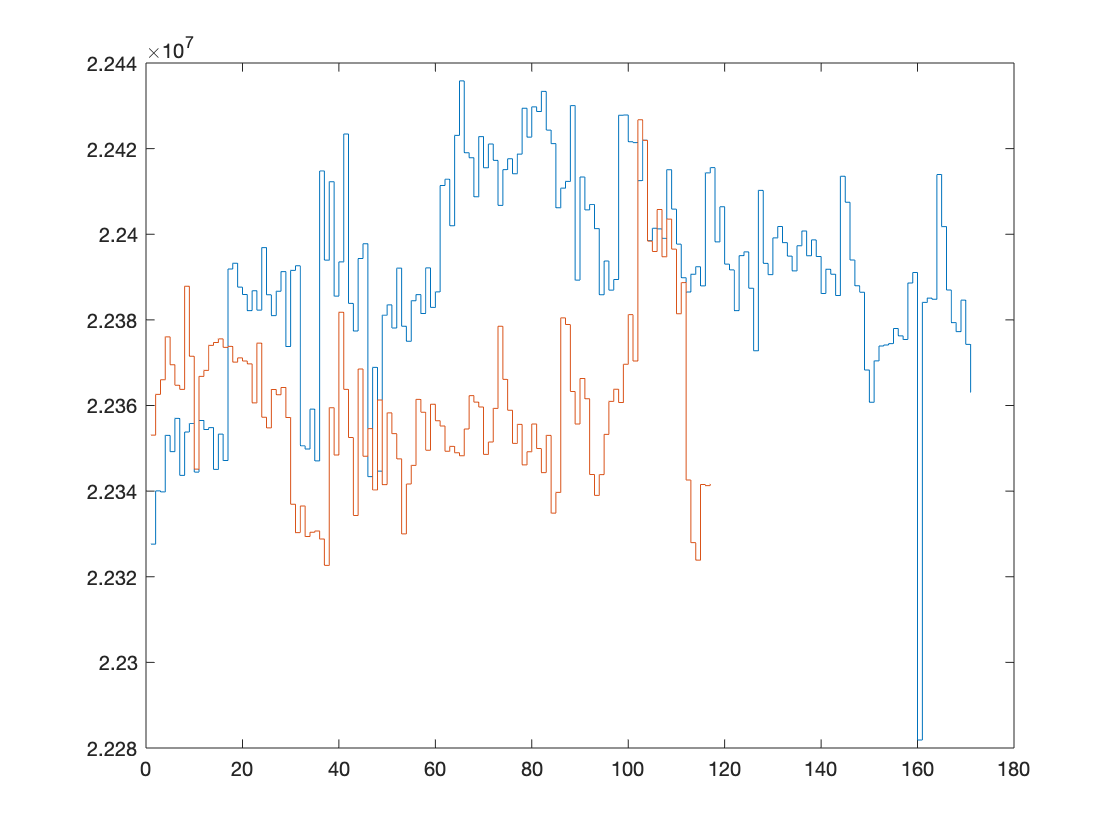

stairs(before)
hold on
stairs(after)
hold off

%Data 
R300before           = fitdist(before','Normal');
R300before_Mean      = R300before.mu

R300before_Mean =      2.239028544133520e+07


R300before_MeanError = sqrt(R300before.ParameterCovariance(1,1))

R300before_MeanError =      1.838177792849887e+03



R300after           = fitdist(after','Normal');
R300after_Mean      = R300after.mu

R300after_Mean =      2.235952375581823e+07


R300after_MeanError = sqrt(R300after.ParameterCovariance(1,1))

R300after_MeanError =      1.770450270395771e+03




b    = [1 2];
x    = [R300before_Mean R300after_Mean];
ex   = [R300before_MeanError R300after_MeanError];
Data = [b' x' ex'];
nbin = 2;

% Fit
parnames = 'mean'; 
ParIni   = mean([R300before_Mean,R300after_Mean]);
Args     = {ParIni, Data, '-c', 'min; imp'};
[ par, err, chi2min, errmat ] = fminuit('Chi2Gauss',Args{:});

  MINUIT RELEASE 96.03  INITIALIZED.   DIMENSIONS 150/150  EPSMAC=  0.89E-15

 PARAMETER DEFINITIONS:
    NO.   NAME         VALUE      STEP SIZE      LIMITS
     1 'mean      '   0.22375E+08  0.22375E+06     no limits
 **********
 **    1 **MIN
 **********

 FIRST CALL TO USER FUNCTION AT NEW START POINT, WITH IFLAG=4.
 START MIGRAD MINIMIZATION.  STRATEGY 1.  CONVERGENCE WHEN EDM .LT. 0.10E-03

 FCN=   145.4873     FROM MIGRAD    STATUS=INITIATE       4 CALLS        5 TOTAL
                     EDM= unknown      STRATEGY= 1      NO ERROR MATRIX       

  EXT PARAMETER               CURRENT GUESS       STEP         FIRST   
  NO.   NAME        VALUE          ERROR          SIZE      DERIVATIVE 
   1     mean      0.22375E+08   0.22375E+06   0.22375E+06   0.70986E-03

 MIGRAD MINIMIZATION HAS CONVERGED.

 MIGRAD WILL VERIFY CONVERGENCE AND ERROR MATRIX.
 COVARIANCE MATRIX CALCULATED SUCCESSFULLY

 FCN=   145.2824     FROM MIGRAD    STATUS=CONVERGED     14 CALLS       15 TOTAL
         

fprintf('=========================== Fit results ========================\n');

=========================== Fit results ========================


fprintf('  mean    = %.3f ± %.3f\n',par(1),err(1));

  mean    = 22374327.460 ± 1275.169


fprintf('  chi2min = %.2f for ndof = %d\n',chi2min,nbin-numel(ParIni));

  chi2min = 145.28 for ndof = 1


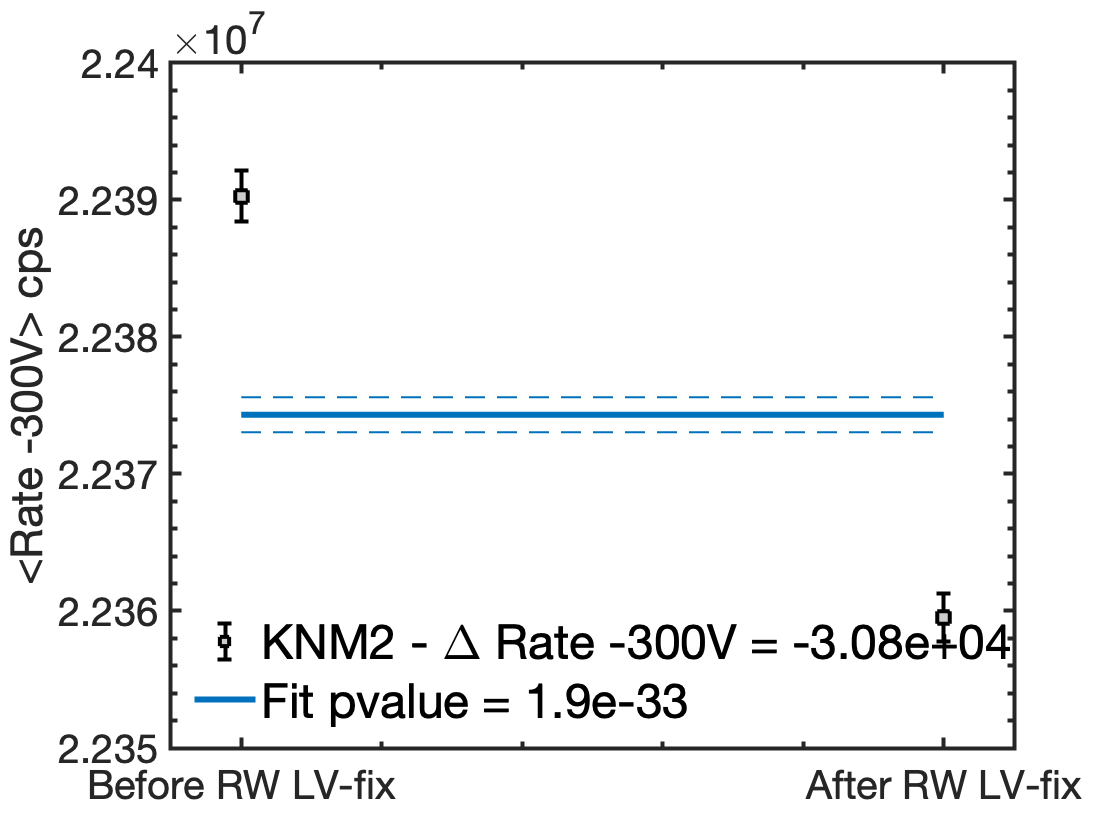


% Display
figure
hdata = errorbar(Data(:,1),Data(:,2),Data(:,3),'ks',...
    'MarkerSize',8,'MarkerFaceColor',.8*[1 1 1],'LineWidth',2);
hold on;
hfit = line([1,2],[Model(par,Data(:,1)) Model(par,Data(:,1))],'LineWidth',3);
hfiteu = line([1,2],[Model(par+err,Data(:,1)) Model(par+err,Data(:,1))],'LineWidth',1,'LineStyle','--');
hfited = line([1,2],[Model(par-err,Data(:,1)) Model(par-err,Data(:,1))],'LineWidth',1,'LineStyle','--');
hold off;
ylabel('<Rate -300V> cps','FontSize',24) 
legend([hdata hfit], ...
    sprintf('KNM2 - \\Delta Rate -300V = %.3g',(R300after_Mean-R300before_Mean)), ...
    sprintf('Fit pvalue = %.2g',chi2pvalue(chi2min,1)),...
    'Location','SouthWest','FontSize',24)
grid off
xlim([0.9 2.1]);
xticks([1 2])
xticklabels({'Before RW LV-fix','After RW LV-fix'})
legend('boxoff');
PrettyFigureFormat('FontSize',24); 

RMDataRateOffsetPerCent = (R300after_Mean-R300before_Mean)/par(1)*100;

fprintf('Shift of -300V Counts %.4f counts wrt %.4g counts (after - before fix)\n',...
    (R300after_Mean-R300before_Mean),...
    par(1));

Shift of -300V Counts -30761.6855 counts wrt 2.237e+07 counts (after - before fix)


fprintf('Shift of -300V Rate %.4f cps wrt %.4g cps (after - before fix : %.3f percent)\n',...
    (R300after_Mean-R300before_Mean)./mean(sstime),...
    par(1)./mean(sstime),...
    RMDataRateOffsetPerCent); 

Shift of -300V Rate -103.4913 cps wrt 7.527e+04 cps (after - before fix : -0.137 percent)


## Interpretation of the After/Before -300V Rate Shift as a shift of the RW Voltage Potential (Assuming Full Coupling)

% Common Arguments
CommonArg = {'RunNr',1,...% has no meaning
    'DataType','Fake',...
    'FSDFlag','BlindingKNM2',...
    'fixPar','Norm E0 Bkg',...
    'ELossFlag','KatrinT2',...
    'AnaFlag','StackPixel',...
    'chi2','chi2Stat',...
    'fitter','minuit',...
    'minuitOpt','min;migrad',...
    'NonPoissonScaleFactor',1
    };
InitFile = @ref_FakeRun_KNM2_CD22_23days_RM;
SpecArg = { 'exclDataStart',1,... % 40eV range
            };
        
T = RunAnalysis(CommonArg{:},SpecArg{:},'FakeInitFile',InitFile);

---------------------Start RunAnalysis Constructor------------------- 
RunAnalysis:ReadData: Reading Tritium Data from File:
                     EffCorr: [39×1 double]
                  ISXsection: 3.642000000000000e-22
                   MACE_Ba_T: 6.300000000000000e-04
                       TBDIS: [39×1 double]
                      TBDISE: [39×1 double]
                     TimeSec: 2592000
       TimeperSubRunperPixel: [39×148 double]
           WGTS_CD_MolPerCm2: 4.200000000000000e+17
    WGTS_CD_MolPerCm2_SubRun: [39×1 double]
             WGTS_MolFrac_DT: 0.011000000000000
      WGTS_MolFrac_DT_SubRun: [39×1 double]
             WGTS_MolFrac_HT: 0.035000000000000
      WGTS_MolFrac_HT_SubRun: [39×1 double]
             WGTS_MolFrac_TT: 0.950000000000000
      WGTS_MolFrac_TT_SubRun: [39×1 double]
                          qU: [39×1 double]
                      qUfrac: [39×1 double]
                     RunName: '1'

loading response function from file: ../../inputs/ResponseFu

T.Fit;

RunAnalysis: Loading (E0 Norm Bkg) for Initialization from file ../../tritium-data/fit/Knm2/FitResult_InitModelObj_E0NormBkg_1.mat 
----------BEGIN FIT MINUIT-------------- 
  MINUIT RELEASE 96.03  INITIALIZED.   DIMENSIONS 150/150  EPSMAC=  0.89E-15

 PARAMETER DEFINITIONS:
    NO.   NAME         VALUE      STEP SIZE      LIMITS
     1 'Par  #1   '    0.0000      0.10000E-04     no limits
     2 'Par  #2   '    0.0000      0.10000E-04     no limits
     3 'Par  #3   '  -0.11253      0.11253E-02     no limits
     4 'Par  #4   '  -0.20994E-11  0.10000E-04     no limits
     5 'Par  #5   '    0.0000      0.10000E-04     no limits
     6 'Par  #6   '    0.0000      0.10000E-04     no limits
     7 'Par  #7   '    0.0000      0.10000E-04     no limits
     8 'Par  #8   '    0.0000      0.10000E-04     no limits
     9 'Par  #9   '    0.0000      0.10000E-04     no limits
    10 'Par #10   '    0.0000      0.10000E-04     no limits
    11 'Par #11   '    0.0000      0.10000E-04     no limi

RefRate = T.ModelObj.TBDIS(1); % ./(T.ModelObj.TimeSec*T.ModelObj.qUfrac(1))

T.ModelObj.nRings = 1; 
T.ModelObj.i_qUOffset = 0; 
T.ModelObj.ComputeTBDDS('qUOffset_bias',-100e-3);
 T.ModelObj.ComputeTBDIS()
 RefMinus50mV =T.ModelObj.TBDIS(1)

RefMinus50mV =      6.926853458578022e+09


counter=0;
clear RateOffset;
offset=-200e-3:10e-3:200e-3;
for quoffset=offset
counter = counter + 1;
T.ModelObj.ComputeTBDDS('qUOffset_bias',quoffset);
T.ModelObj.ComputeTBDIS()
RateOffset(counter) = T.ModelObj.TBDIS(1);
end


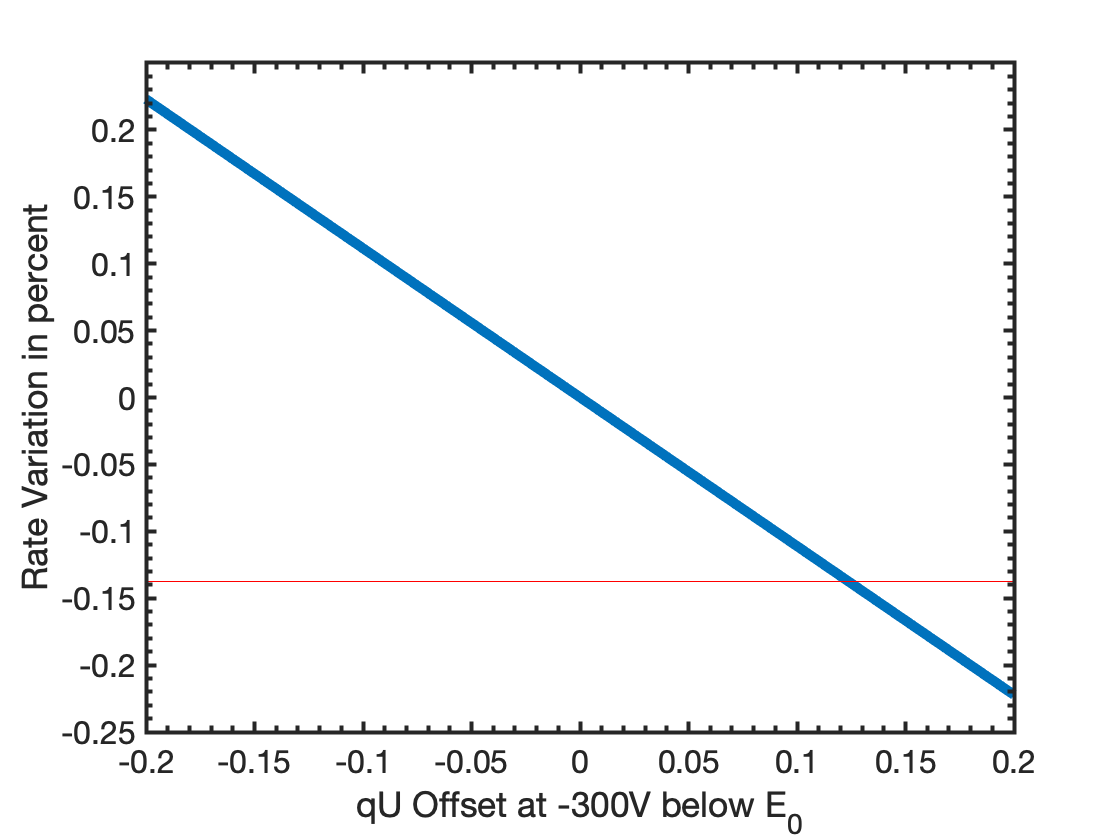

plot(offset,(RateOffset-RefRate)/RefRate*100,'Linewidth',5);
hold on
line([-0.2 0.2],[RMDataRateOffsetPerCent RMDataRateOffsetPerCent],'Color','Red');
hold off
xlabel('qU Offset at -300V below E_0');
ylabel('Rate Variation in percent');
PrettyFigureFormat;